clear
fy=@(x,y)4-2*x.*y;
y0=0.2;
%tspan=[0,1];
tspan=0:0.1:1;
[x,y]=ode45(fy,tspan,y0)

x =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


y =     0.2000
    0.5954
    0.9712
    1.3133
    1.6102
    1.8535
    2.0386
    2.1645
    2.2339
    2.2519


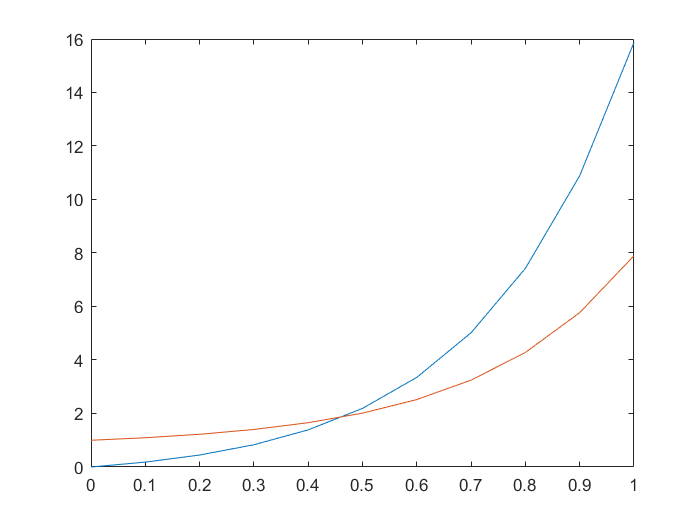

clear
fy=@(x,y)[3*y(1)+1.5*y(2);1.2*y(1)+0.8*y(2)];
y0=[0;1];
tspan=0:0.1:1;
[x,y]=ode45(fy,tspan,y0);
plot(x,y(:,1),x,y(:,2))

dataxy=[x,y];
%save('exa1.xls','dataxy','-ascii','-tabs')
%xlswrite('exa1.xls',dataxy,2,'A2')

%二阶化为一阶，yi=y,y2=y'
%y1'=y2',y2'=sin5x-5y1
clear
fy=@(x,y)[y(2);sin(5*x)-55*y(1)];
y0=[1.2;0];tspan=0:0.1:6;
[x,y]=ode45(fy,tspan,y0);

%tic start;toc end
fy=@(x,y)[y(2);1000*(1-y(1).*y(1)).*y(2)-y(1)];
y0=[2;0];
tspan=0:1:300;
tic
[x,y]=ode15s(fy,tspan,y0);
timest=toc

timest = 0.4399

clear
fy=@(x,y,dy)[dy(1).*sin(y(1))+dy(2).*cos(y(2))+2*y(1)-1;-dy(1).*cos(y(2))+dy(2).*cos(y(1))+3*y(2)];
y0=[0.1;0.2];
dy0=[0;1];
tspan=0:12;
[x,y]=ode15i(fy,tspan,y0,dy0);

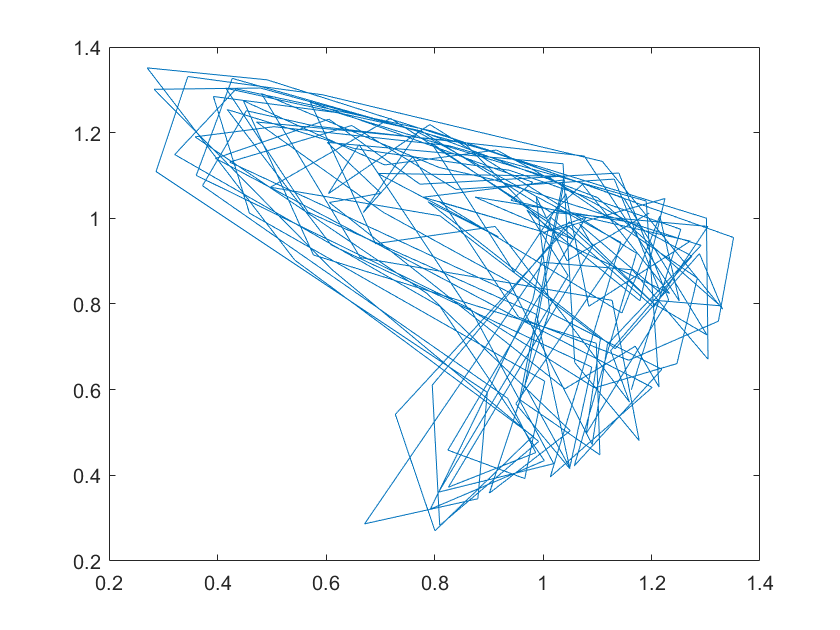

%滞后，延时常微分方程
%dde23,lags延迟常数，行向量
clear
lags=3;history=0.6;
fy=@(x,y,z)2*z./(1+z.^9.64)-y;
tspan=0:199;t=3:199;
sol=dde23(fy,lags,history,tspan);
y=deval(sol,t);
ylag=deval(sol,t-3);
plot(y,ylag)

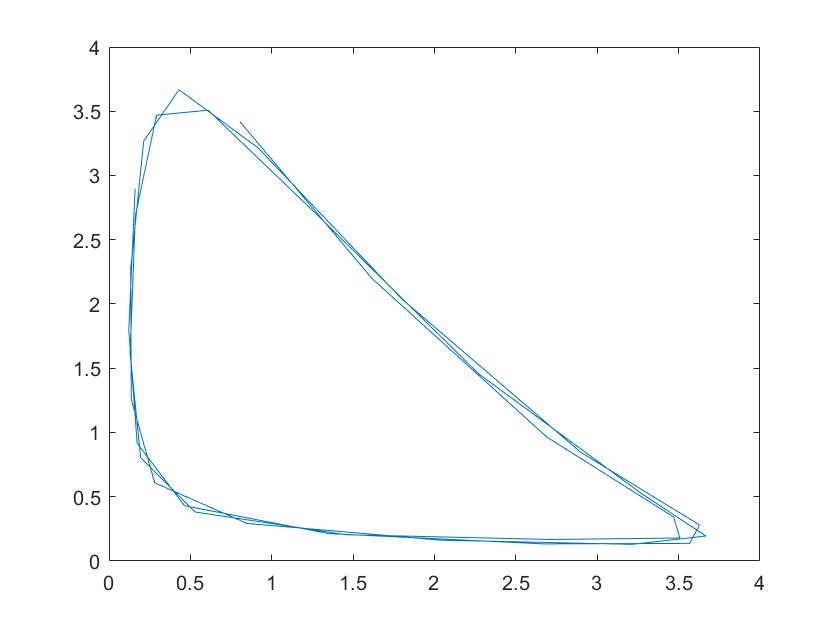

clear
lags=[1 8];
history=[4.5;0.1;0.8];
tspan=[0,45];t=10:45;
fy=@(x,y,z)[-y(1).*z(2,1)+z(2,2);y(1).*z(2,1)-y(2);y(2)-z(2,2)];
sol=dde23(fy,lags,history,tspan);
y1=deval(sol,t,1);
y1lag=deval(sol,t-8,1);
plot(y1,y1lag)

clear
lags=@(x,y)exp(1-y(2));
fy=@(x,y,z)[y(2);-z(2)*y(2).*y(2)*exp(1-y(2))];
history=@(t)[log(t);1/t];
tspan=[0.1,5];
sol=ddesd(fy,lags,history,tspan);
y1=deval(sol,tspan,1)

y1 =    -2.3026    1.6093


%边值问题
%y1'=y2,y2'=...
clear
fy=@(x,y)[y(2);(2*x.*y(2)-2*y(1))./(1+x.*x)+1];
solinit=bvpinit(linspace(0,4,5),[1.25 1.25]);
bc=@(ya,yb)[ya(1)-1.25;yb(1)+0.95];
sol=bvp4c(fy,bc,solinit)

sol = 包含以下字段的 struct :
    solver: 'bvp4c'
         x: [0 0.2500 0.5000 0.7500 1 1.5000 2 2.5000 3 3.5000 3.7500 4]
         y: [2×12 double]
        yp: [2×12 double]
     stats: [1×1 struct]
